clc
clear all

df = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vSldoEABS4unIo8FZLtaLXT-mlEg5zJBRFAXG3_BqxaTd1Eq70ckcpApEHEQNju09iylNCpRuzw5lT3/pub?gid=2013391921&single=true&output=csv")

df = 31×8 table
     v1       i1        v2       i2        v3       i3        v4       i4   
    ____    _______    ____    _______    ____    _______    ____    _______

    1.65    0.00315     0.5    0.00085    0.85    0.00085       1     0.0009
    2.15    0.00425    0.75     0.0013     1.1     0.0011     1.3     0.0012
     2.3    0.00475     1.2     0.0021     1.3     0.0013     1.7     0.0015
     2.5     0.0051     1.7      0.003     1.6     0.0016     1.8     0.0016
     2.9    0.00595     1.9    0.00325     2.1      0.002    2.25      0.002
     3.2     0.0065    2.15     0.0036     2.4    0.00225     2.5     0.0022
     3.4    0.00695     2.5     0.0044     2.6     0.0025     2.8    0.00245
    3.65     0.007

% conclusioni
conc = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vSldoEABS4unIo8FZLtaLXT-mlEg5zJBRFAXG3_BqxaTd1Eq70ckcpApEHEQNju09iylNCpRuzw5lT3/pub?gid=1924196415&single=true&output=csv")

conc = 20×4 table
     R      dR           description            type
    ____    __    __________________________    ____

     491    21    {'media r1t A'           }     1  
     494    21    {'media r1 A'            }     1  
     468     1    {'valore misurato tester'}     1  
     470    23    {'valore noto'           }     1  
     490     2    {'best-fit'              }     1  
     575    37    {'media r1t B'           }     2  
     499    37    {'media r1 B'            }     2  
     468     1    {'valore misurato tester'}     2  
     470    23    {'valore noto'           }     2  
     579     4    {'best-fit'              }     2  
    1035    48    {'media r2t A'           }     3  
    1049    49    {'media r2 A'            }     3  
     993     1    {'valore misurato tester'}     3  
    1000    50    {'valore noto'           }     3

% best fit
bf = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vSldoEABS4unIo8FZLtaLXT-mlEg5zJBRFAXG3_BqxaTd1Eq70ckcpApEHEQNju09iylNCpRuzw5lT3/pub?gid=1333346124&single=true&output=csv")

bf = 4×4 table
    conf       m1         q1           m2    
    ____    ________    _______    __________

     1       0.00214    -0.0003      0.002055
     2       0.00176     -5e-05     0.0017417
     3       0.00097     -2e-05    0.00096226
     4      0.000885          0    0.00087909


di = 0.0001;
dv = 0.1;

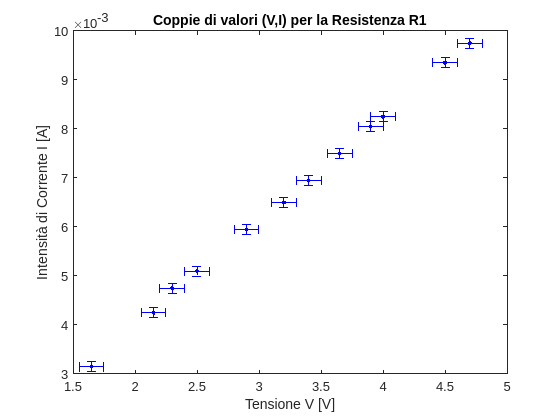

v1 = colnan(df.v1);
i1 = colnan(df.i1);

fig=figure;
errorbar(v1,i1,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R1")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-1.png")

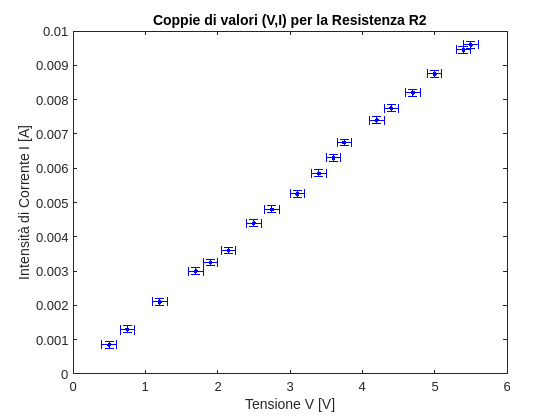


v2 = colnan(df.v2);
i2 = colnan(df.i2);

fig=figure;
errorbar(v2,i2,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R2")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-2.png")

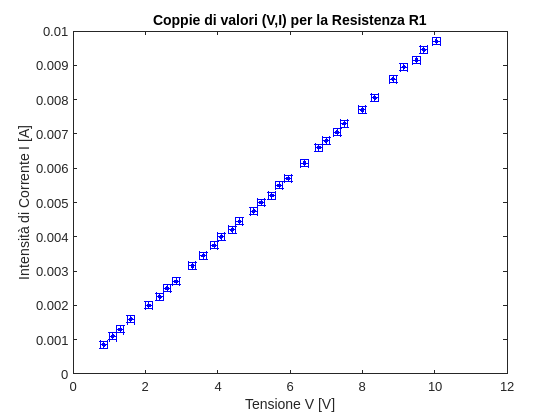


v3 = colnan(df.v3);
i3 = colnan(df.i3);

fig=figure;
errorbar(v3,i3,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R1")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-3.png")

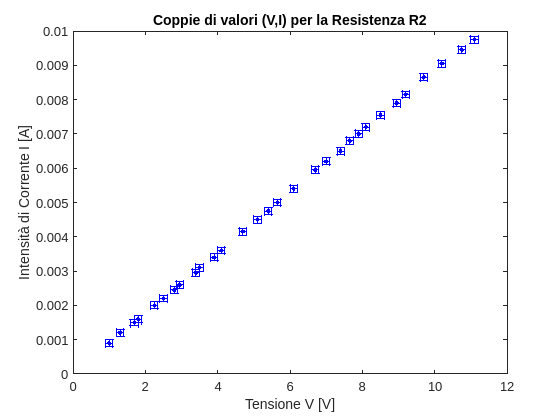


v4 = colnan(df.v4);
i4 = colnan(df.i4);

fig=figure;
errorbar(v4,i4,di,di,dv,dv,'.','Color','b')
title("Coppie di valori (V,I) per la Resistenza R2")
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
saveas(fig,"../img/fede-4.png")

% best fit
m1 = bf.m1;
q1 = bf.q1;
m2 = bf.m2;

tp = 4

tp = 4

v = v4

v =     1.0000
    1.3000
    1.7000
    1.8000
    2.2500
    2.5000
    2.8000
    2.9500
    3.4000
    3.5000


i = i4

i =     0.0009
    0.0012
    0.0015
    0.0016
    0.0020
    0.0022
    0.0024
    0.0026
    0.0029
    0.0031



yfit1 = m1(tp).*v + q1(tp);
yfit2 = m2(tp).*v;

fig = figure;
errorbar(v,i,di,di,dv,dv,'.','Color','b')
hold on
plot(v,yfit1)
plot(v,yfit2)
hold off
xlabel("Tensione V [V]")
ylabel("Intensità di Corrente I [A]")
legend("Dati osservati","y = mx + q","y = mx",Location="best")
s = "../img/" + sprintf("bestfit-fede-%i.png",tp)

s = "../img/bestfit-fede-4.png"

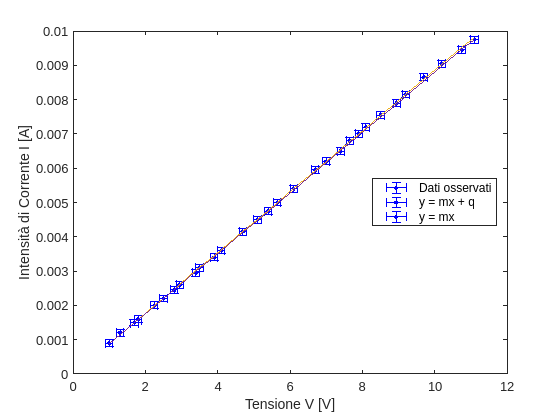

saveas(fig,s)

clear fig

tp = 4

tp = 4


R = table2array(conc(conc.type==tp,"R"))

R =         1130
        1054
         993
        1000
        1061


dr = table2array(conc(conc.type==tp,"dR"))

dr =     51
    51
     1
    50
     4



fig = figure;
errorbar(1:5,R,dr,dr,'.')
title("Resistenza R2, circuito B")
ylabel("R [cm]")
xlim([0 6])

s = "../img/" + sprintf("conclusioni-fede-%i.png",tp)

s = "../img/conclusioni-fede-4.png"

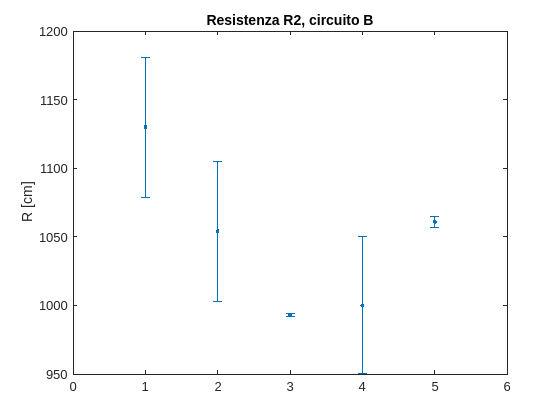


saveas(fig,s)

function c = colnan(x)
    ni = isnan(x);
    c = x(~ni);
end